# GEM Analysis

## Set up filepaths

% Find the ssADGEM project dir location
script_path = fileparts(matlab.desktop.editor.getActiveFilename);
project_path = extractBefore(script_path, "code");
clear script_path;

% Add code dir to path
addpath(strjoin([project_path, "code"], ""))

% Find the GEM dir
GEMs_dir = strjoin([project_path, "data/ROSMAP_GEMs/"], "");

% Get hash key
hash_key = readtable( ...
    strjoin([project_path, "data/HASH_key.csv"], ""), ...
    "Delimiter",",");


% Get metadata
metadata = readtable(strjoin([project_path, ...
    "data/ROSMAP_metadata.csv"], ""));
metadata.Properties.VariableNames(1) = {'SampleID'};
for i = 1:length(metadata.SampleID)
    if metadata.SampleID{i} == hash_key.Samples{i}
        metadata.SampleID{i} = strjoin(["ROSMAP_", hash_key.Hash{i}, ".mat"], "");
    else
        hashed_id = hash_key.Hash{strcmp(hash_key.Samples, metadata.SampleID{i})};
        metadata.SampleID{i} = strjoin(["ROSMAP_", hashed_id, ".mat"], "");
    end
end

% Make order alphabetical (like file order)
metadata.SampleID = cellfun(@(x) x{:}, metadata.SampleID, 'UniformOutput', false);
metadata = sortrows(metadata, 'SampleID');

## Run comparison

### Set batch to compare

eligible_batches = string(unique(metadata.Batch));
batch = str2num(eligible_batches(9));

### Get comparison structure

% If model comparison already exists, use that
model_comparison_path = strjoin([project_path, ...
    "data/model_comparison", batch, ".mat"], "");
structComp_csv_path = strjoin([project_path, ...
    "data/structCompBatch", batch, ".csv"], "");

if isfile(model_comparison_path)
    model_comparison = load(model_comparison_path).model_comparison;
else
    models = models2cell_array(GEMs_dir);
    model_comparison = compareMultipleModels(models(metadata.Batch == batch));
    save(model_comparison_path, "model_comparison");
    writematrix(model_comparison.structComp, ...
        structComp_csv_path)
end
clear model_comparison_path;

% Remove any metadata with no model
metadata_all = metadata;
metadata = metadata( ...
    ismember(metadata.SampleID, model_comparison.modelIDs), ...
    :);

## Analyse results

plot_dir = strjoin([project_path, ...
    "nobackup/plots/"], "");

### Clustergram

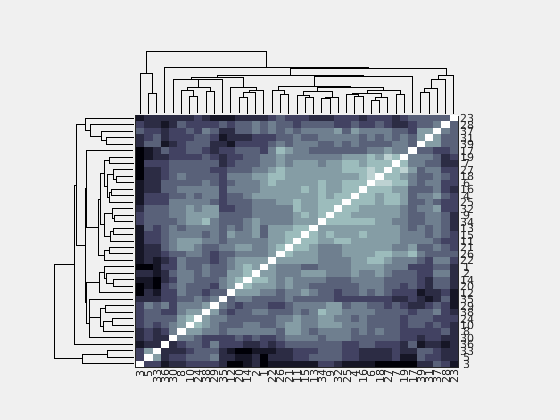

cg = clustergram(model_comparison.structComp, ...
    'Symmetric', false, ...
    'Colormap', 'bone');
close all hidden
clc
figure
p = plot(cg);
saveas(p, strjoin([plot_dir, ...
    "gem_clustergram_batch", batch, ".png"], ""));

clf

### Set grouping variable

metadata_columns = string(metadata.Properties.VariableNames);
metadata_columns = metadata_columns(2:end);
grouping = metadata_columns(1);
is_grouping_categorical = 7 > length(unique(metadata.(grouping)));

### PCA

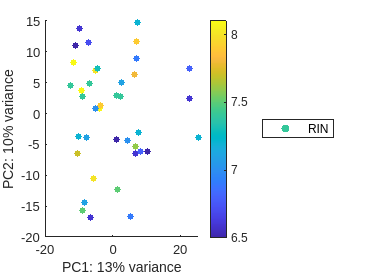

[~,scores,~,~,explained] = pca(model_comparison.reactions.matrix');
f = figure;
plotByGrouping(scores(:,1), scores(:,2), metadata.(grouping), is_grouping_categorical, grouping);
xlabel(['PC1: ', num2str(explained(1), 2), '% variance'])
ylabel(['PC2: ', num2str(explained(2), 2), '% variance'])
legend('Location','eastoutside')
exportgraphics(f,strjoin([plot_dir, ...
    "gem_pca_batch", batch, "_grouping_", grouping, ".png"], ""));

clf

### t-SNE

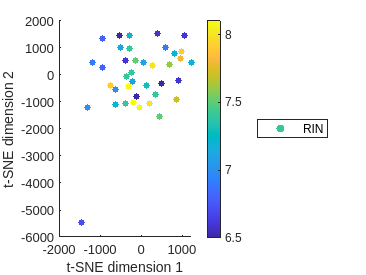

rxn2Dmap = tsne(model_comparison.reactions.matrix', 'Distance', 'hamming', 'NumDimensions', 2, 'Perplexity', 5);
f = figure;
plotByGrouping(rxn2Dmap(:,1), rxn2Dmap(:,2), metadata.(grouping), is_grouping_categorical, grouping);
xlabel('t-SNE dimension 1')
ylabel('t-SNE dimension 2')
legend('Location','eastoutside')
exportgraphics(f,strjoin([plot_dir, ...
    "gem_scatter_batch", batch, "_grouping_", grouping, ".png"], ""));

clf

### Subsystem Coverage

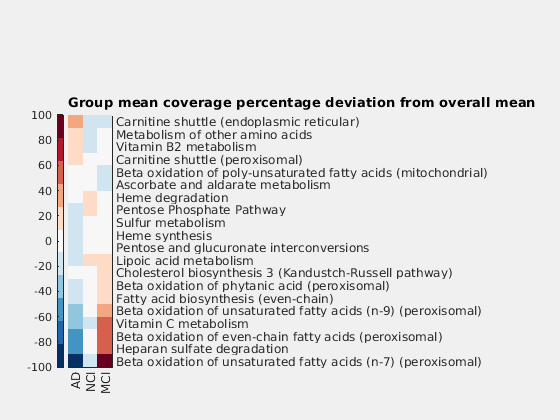

cogdx = unique(metadata.cogdx);
no_subsystems = height(model_comparison.subsystems.matrix);
cogdxCoverages = zeros(no_subsystems, length(cogdx));
for i = 1:length(cogdx)
    idx = ismember(metadata.cogdx, cogdx{i});
    cogdxCoverages(:, i) = mean(model_comparison.subsystems.matrix(:, idx), 2);
end
subMat = cogdxCoverages;
subCoverage = (subMat - mean(subMat, 2)) ./ mean(subMat, 2) * 100;

% select subsystems to include in plot
inclSub = any(abs(subCoverage) > 10, 2);
subNames = model_comparison.subsystems.ID(inclSub);

% generate clustergram
cg = clustergram(subCoverage(inclSub, :), ...
    'Colormap',redbluecmap, ...
    'DisplayRange', 100, ...
    'rowLabels', subNames, ...
    'columnLabels', cogdx, ...
    'ShowDendrogram', 'OFF');
close all hidden
clc
figure
p = plot(cg);
p.XLim(2) = 3.5;
p.Position(1) = .05;
p.Position(3) = .15;
colorbar(p,'westoutside');
title(p,'Group mean coverage percentage deviation from overall mean');
p.TitleHorizontalAlignment = 'left';
saveas(p, strjoin([plot_dir, ...
    "gem_subsystem_batch", batch, ".png"], ""));

clf

## Subsystem coverage overlap between batches

% If model comparison already exists, use that
model_comparison_path = strjoin([project_path, ...
    "data/model_comparison.mat"], "");
structComp_csv_path = strjoin([project_path, ...
    "data/structCompBatch.csv"], "");

if isfile(model_comparison_path)
    model_comparison_all = load(model_comparison_path).model_comparison_all;
else
    models = models2cell_array(GEMs_dir);
    model_comparison_all = compareMultipleModels(models);
    save(model_comparison_path, "model_comparison_all");
    writematrix(model_comparison_all.structComp, ...
        structComp_csv_path)
end
clear model_comparison_path;

### By cogdx

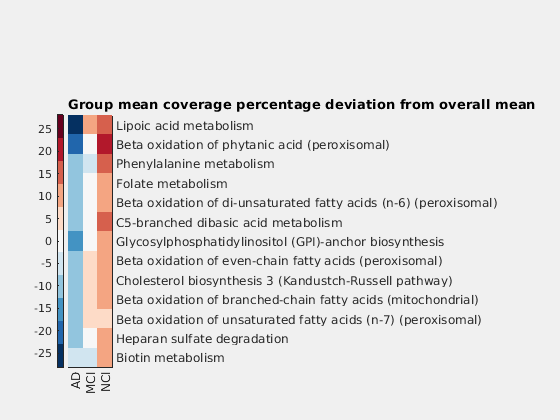

no_subsystems = height(model_comparison_all.subsystems.matrix);
cogdxCoverages = zeros(no_subsystems, length(cogdx));
for i = 1:length(cogdx)
    idx = ismember(metadata_all.cogdx, cogdx{i});
    cogdxCoverages(:, i) = mean(model_comparison_all.subsystems.matrix(:, idx), 2);
end
subMat = cogdxCoverages;
subCoverage = (subMat - mean(subMat, 2)) ./ mean(subMat, 2) * 100;

% select subsystems to include in plot
inclSub = any(abs(subCoverage) > 10, 2);
subNames = model_comparison_all.subsystems.ID(inclSub);

% generate clustergram
cg = clustergram(subCoverage(inclSub, :), ...
    'Colormap',redbluecmap, ...
    'DisplayRange', 100, ...
    'rowLabels', subNames, ...
    'columnLabels', cogdx, ...
    'ShowDendrogram', 'OFF');
close all hidden
clc
figure
p = plot(cg);
p.XLim(2) = 3.5;
p.Position(1) = .05;
p.Position(3) = .15;
colorbar(p,'westoutside');
title(p,'Group mean coverage percentage deviation from overall mean');
p.TitleHorizontalAlignment = 'left';
saveas(p, strjoin([plot_dir, ...
    "gem_subsystem_all_cogdx.png"], ""));

clf

### By ceradsc

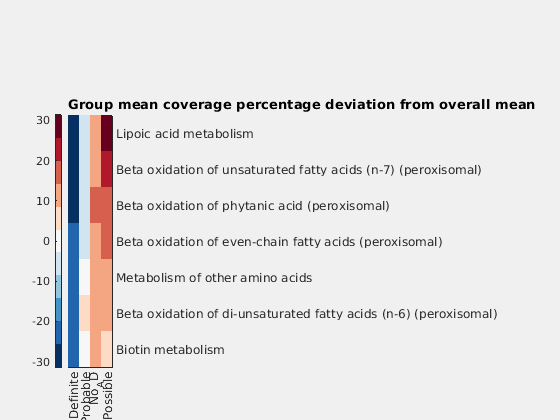

ceradsc = unique(metadata_all.ceradsc);
no_subsystems = height(model_comparison_all.subsystems.matrix);
ceradscCoverages = zeros(no_subsystems, length(ceradsc));
for i = 1:length(ceradsc)
    idx = ismember(metadata_all.ceradsc, ceradsc{i});
    ceradscCoverages(:, i) = mean(model_comparison_all.subsystems.matrix(:, idx), 2);
end
subMat = ceradscCoverages;
subCoverage = (subMat - mean(subMat, 2)) ./ mean(subMat, 2) * 100;

% select subsystems to include in plot
inclSub = any(abs(subCoverage) > 20, 2);
subNames = model_comparison_all.subsystems.ID(inclSub);

% generate clustergram
cg = clustergram(subCoverage(inclSub, :), ...
    'Colormap',redbluecmap, ...
    'DisplayRange', 100, ...
    'rowLabels', subNames, ...
    'columnLabels', ceradsc, ...
    'ShowDendrogram', 'OFF');
close all hidden
clc
figure
p = plot(cg);
p.XLim(2) = 4.5;
p.Position(1) = .05;
p.Position(3) = .15;
colorbar(p,'westoutside');
title(p,'Group mean coverage percentage deviation from overall mean');
p.TitleHorizontalAlignment = 'left';
saveas(p, strjoin([plot_dir, ...
    "gem_subsystem_all_ceradsc.png"], ""));

clf

### By ceradsc_binary

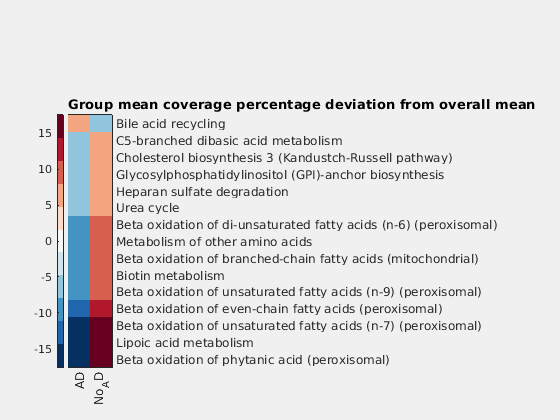

ceradsc_binary = unique(metadata_all.ceradsc_binary);
no_subsystems = height(model_comparison_all.subsystems.matrix);
ceradsc_binaryCoverages = zeros(no_subsystems, length(ceradsc_binary));
for i = 1:length(ceradsc_binary)
    idx = ismember(metadata_all.ceradsc_binary, ceradsc_binary{i});
    ceradsc_binaryCoverages(:, i) = mean(model_comparison_all.subsystems.matrix(:, idx), 2);
end
subMat = ceradsc_binaryCoverages;
subCoverage = (subMat - mean(subMat, 2)) ./ mean(subMat, 2) * 100;

% select subsystems to include in plot
inclSub = any(abs(subCoverage) > 5, 2);
subNames = model_comparison_all.subsystems.ID(inclSub);

% generate clustergram
cg = clustergram(subCoverage(inclSub, :), ...
    'Colormap',redbluecmap, ...
    'DisplayRange', 100, ...
    'rowLabels', subNames, ...
    'columnLabels', ceradsc_binary, ...
    'ShowDendrogram', 'OFF');
close all hidden
clc
figure
p = plot(cg);
p.XLim(2) = 2.5;
p.Position(1) = .05;
p.Position(3) = .15;
colorbar(p,'westoutside');
title(p,'Group mean coverage percentage deviation from overall mean');
p.TitleHorizontalAlignment = 'left';
saveas(p, strjoin([plot_dir, ...
    "gem_subsystem_all_ceradsc_binary.png"], ""));

clf

## Clean up

rmpath(strjoin([project_path, "code"], ""))

## Functions

function plt = plotByGrouping(x,y, column_data, is_categorical, grouping_name)
    if is_categorical
        column_data = strrep(column_data, "_", " ");
        gscatter(x,y,column_data)
    else
        grouping_name = strrep(grouping_name, "_", " ");
        scatter(x,y, 25, column_data, "filled", "DisplayName", grouping_name)
        colorbar
    end
end